clear
clc
close all

Simbolicamente

syms s R L bm K_motor k_resorte m_total

% Matrices simbólicas
A = [  0,                 1,                    0;
      -k_resorte/m_total, -bm/m_total,          K_motor/m_total;
       0,                -K_motor/L,            -R/L ];

Bu = [0; 0; 1/L];
Bd = [0; -1/m_total; 0];

C = [1 0 0;
     -k_resorte/m_total, -bm/m_total, K_motor/m_total];

Du = [0; 0];
Dd = [0; -1/m_total];

% Matriz de transferencia simbólica desde u: G(s) = C * (sI - A)^(-1) * Bu + Du
I = eye(3);
G_u = simplify( C * inv(s*I - A) * Bu + Du );  % entrada: voltaje
G_u = collect(G_u,s)

$$G\_u = \begin{array}{l} \left(\begin{array}{c} \frac{K_{\mathrm{motor}}}{\sigma_{1}}\\ \frac{K_{\mathrm{motor}}\,s^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(L\,m_{\mathrm{total}}\right)\,s^{3}+\left(L\,\mathrm{bm}+R\,m_{\mathrm{total}}\right)\,s^{2}+\left({K_{\mathrm{motor}}}^{2}+R\,\mathrm{bm}+L\,k_{\mathrm{resorte}}\right)\,s+R\,k_{\mathrm{resorte}} \end{array}$$

G_d = simplify( C * inv(s*I - A) * Bd + Dd );  % entrada: perturbación
G_d = collect(G_d,s)

$$G\_d = \begin{array}{l} \left(\begin{array}{c} \frac{\left(-L\right)\,s-R}{\sigma_{1}}\\ \frac{\left(-L\right)\,s^{3}+\left(-R\right)\,s^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(L\,m_{\mathrm{total}}\right)\,s^{3}+\left(L\,\mathrm{bm}+R\,m_{\mathrm{total}}\right)\,s^{2}+\left({K_{\mathrm{motor}}}^{2}+R\,\mathrm{bm}+L\,k_{\mathrm{resorte}}\right)\,s+R\,k_{\mathrm{resorte}} \end{array}$$

Parámetros

m_movil = 0.94; % [kg] Masa plato + bobina
m_cubesat = 1.33; %[kg] Masa Cubesat
m_total = m_movil + m_cubesat;
bm = 2; % [Ns/m] coeficiente de fricción viscosa (a confirmar)
k_resorte = 15761; % [N/m]
K_motor = 51.6; %[N/A] [Vs/m] constante de back EMF y de fuerza (valen lo mismo)
g = 9.81; %[m/s^2] Aceleración de la gravedad

R = 3; %[Ohm] Resistencia del bobinado
L = 1.9e-3; %[H] Inductancia del bobinado (medida a 1000Hz)

Pot_max = 75 ; %[W] Potencia máxima
I_max = sqrt(Pot_max/R); % [A]
V_max = sqrt(Pot_max*R); % [V]

K_motor_virtual = K_motor;
bm_virtual = bm;
m_total_virtual = m_total;

f = 500; % Hz
Amp = 1;
Ventana = 100;

Espacio de Estados

%[x
% x' 
% i]

A = [0 1 0;
    -k_resorte/m_total -bm/m_total K_motor/m_total;
    0 -K_motor/L -R/L];
Bu = [0 ; 0 ; 1/L];
Bd = [0; -1/m_total ; 0];
C = [1 0 0;
     -k_resorte/m_total -bm/m_total K_motor/m_total];
Du = [0;0];
Dd = [0;-1/m_total];

sys_c = ss(A,Bu,C,Du);
sys_per = ss(A,Bd,C,Dd);

Hc = tf(sys_c)

Hc =
 
  From input to output...
                      1.196e04
   1:  --------------------------------------
       s^3 + 1580 s^2 + 6.257e05 s + 1.096e07
 
                    1.196e04 s^2
   2:  --------------------------------------
       s^3 + 1580 s^2 + 6.257e05 s + 1.096e07
 
Continuous-time transfer function.



Hd = tf(sys_per)

Hd =
 
  From input to output...
                 -0.4405 s - 695.6
   1:  --------------------------------------
       s^3 + 1580 s^2 + 6.257e05 s + 1.096e07
 
              -0.4405 s^3 - 695.6 s^2
   2:  --------------------------------------
       s^3 + 1580 s^2 + 6.257e05 s + 1.096e07
 
Continuous-time transfer function.



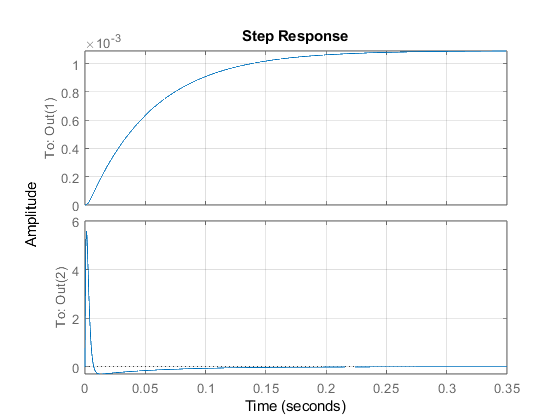


step(sys_c)
grid on

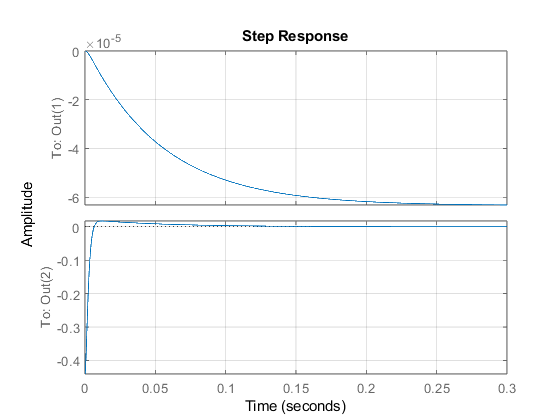

step(sys_per)
grid on

Controlabilidad

Cont = rank([Bu A*Bu A*A*Bu])

Cont = 3

Es completamente controlable desde la entrada de voltaje V

ob = obsv(A, C(2,:))

ob = 	1.0e+09 *

   -0.0000   -0.0000    0.0000
    0.0000   -0.0006   -0.0000
    4.3345    0.9758    0.0425


rank_ob = rank(ob);

if rank_ob == size(A,1)
    disp('El sistema es observable.');
else
    disp(['NO es observable. Rank = ', num2str(rank_ob)]);
end

El sistema es observable.


Control proporcional de corriente

wc_corr = 5000; %Frecuencia de corte
R_control = wc_corr * L;


PID en cascada

zita = 0.7;
wp = wpfreq(f);

ba = m_total_virtual*(2*zita+1)*wp

ba = 544.8000

ksi = m_total_virtual*(2*zita+1)*wp^2*10

ksi = 5.4480e+05

ksia = m_total_virtual*wp^3

ksia = 2270000

function wp = wpfreq(f)
    % Tabla de frecuencia (Hz) y valores correspondientes de wp
    freq_table = [ ...
          5,  10,  20,  25,  30,  40,  50,  60,  70,  80, ...
         90, 100, 200, 300, 400, 500, 1000, 1500, 2000];

    wp_table = [ ...
         20,  15,  18,  20,  22,  25,  25,  25,  30,  30, ...
         40,  40,  50,  50,  70, 100,  200,  200,  200];

    % Interpolación lineal
    wp = interp1(freq_table, wp_table, f, 'linear', 'extrap');
end